data = load("resultadosCSV_500khz.txt");
length(data)

ans =        10240



stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*500e3)

T_buscado =      1.000000000000000e-06


tiempo_muerto = 15*5e-9

tiempo_muerto =      7.500000000000000e-08


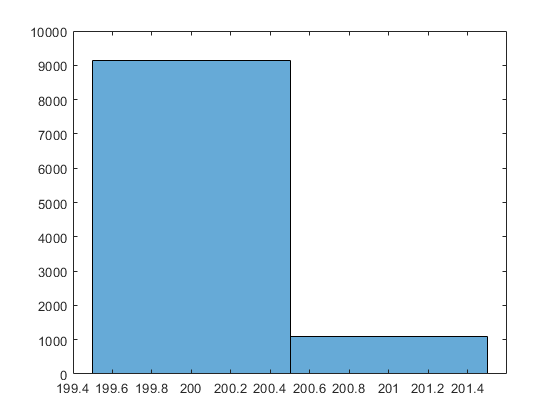

% t_fino = (start)*tau_start - (stop)*tau_stop;
t_fino = (start-stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse)

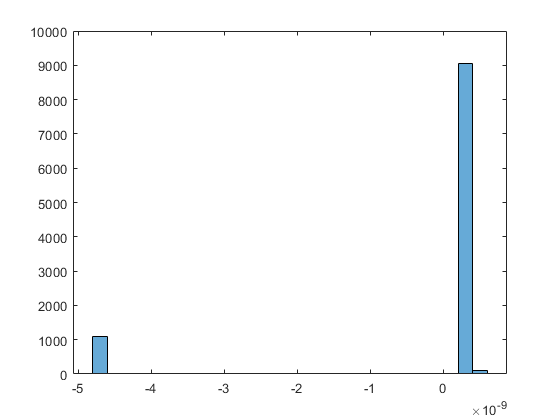

histogram(t_fino)

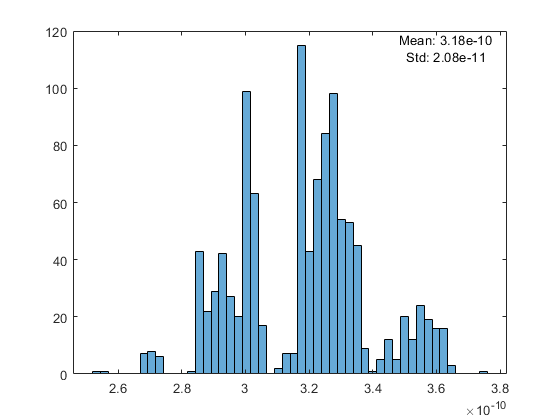


%%finos 201 cuentas
clf;
indices_201 = find(coarse==201);
fino_201 = t_fino(indices_201);
coarse_201 = coarse(indices_201);
mean_201 = mean(fino_201);
std_201 = std(fino_201);
histogram(fino_201, 50);
text(max(xlim)*0.95, max(ylim)*0.95, sprintf('Mean: %.2e\nStd: %.2e', mean_201, std_201), 'HorizontalAlignment', 'center');

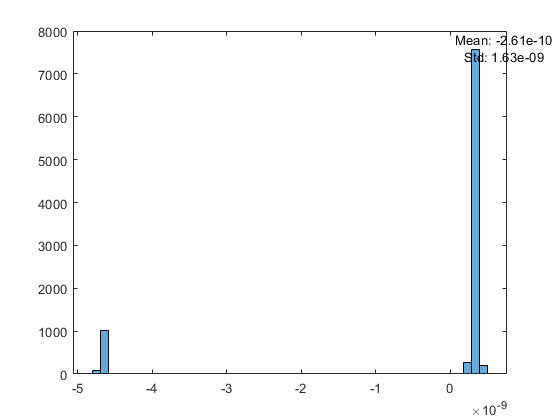


%%finos 200
clf;
indices_200 = find(coarse==200);
fino_200 = t_fino(indices_200);
coarse_200 = coarse(indices_200);
mean_200 = mean(fino_200);
std_200 = std(fino_200);
histogram(fino_200, 50);
text(max(xlim)*0.95, max(ylim)*0.95, sprintf('Mean: %.2e\nStd: %.2e', mean_200, std_200), 'HorizontalAlignment', 'center');

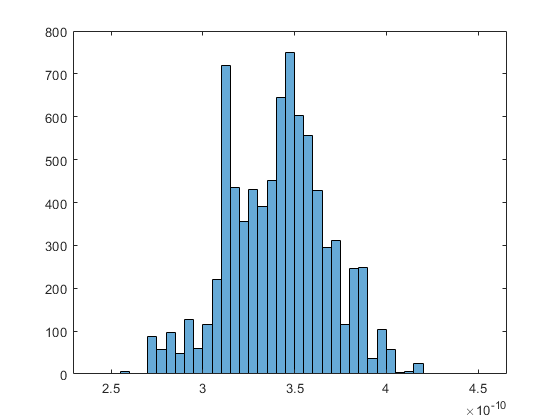


fino_200_buenos = fino_200(fino_200>=0);
coarse_200_buenos = coarse_200(fino_200>=0);
mean(fino_200_buenos);
histogram(fino_200_buenos)


fino_200_malos = fino_200(fino_200<0);
coarse_200_malos = coarse_200(fino_200<0);
find(fino_200<0)

ans =    185
   186
   187
   188
   189
   190
   191
   192
   193
   194


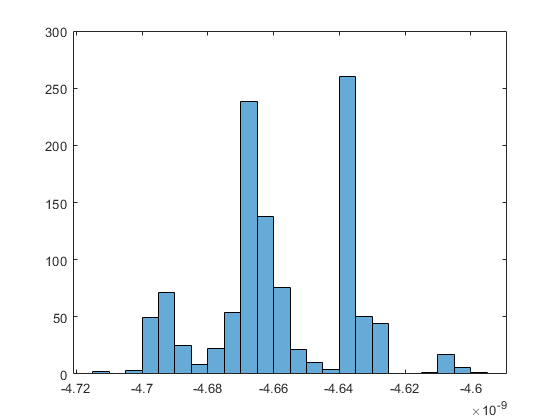

%%los errores ahora son por StartEdge
mean(fino_200_malos);
histogram(fino_200_malos)
text(max(xlim)*0.95, max(ylim)*0.95, sprintf('Mean: %.2e\nStd: %.2e', mean(fino_200_malos), std(fino_200_malos)), 'HorizontalAlignment', 'center');

st = start-stop

st =     14
    13
    14
    12
    12
    10
    14
    14
    12
    14


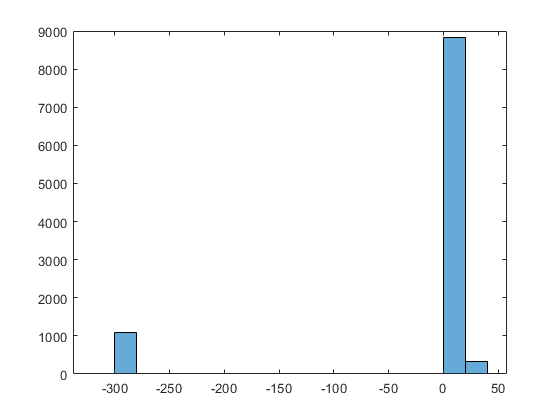

histogram(st)

indices_st = find(st>0)

indices_st =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


st_positivo = st(indices_st);
std(st_positivo)

ans =    2.505753758957175


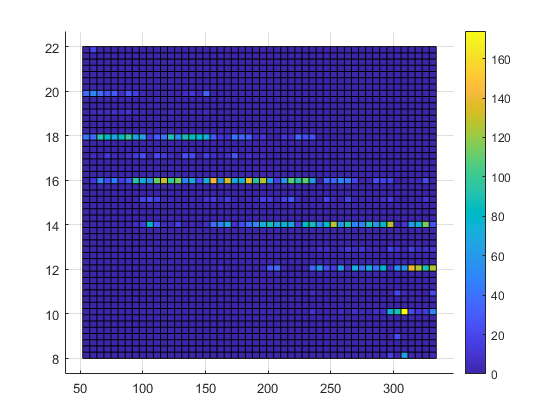

hist3([start(indices_st), st_positivo], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar;
exportgraphics(gcf,'start-stop_500k.eps');

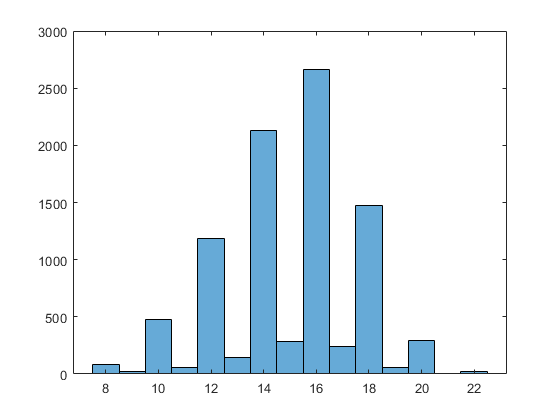

histogram(st(st>0))

clf;
y = [fino_201; fino_200_buenos; (fino_200_malos+T)];
length(y)

ans =        10240


coarse_correcto = 200;

N = 100;
h_201 = histogram(fino_201, N, 'FaceAlpha', 0.5);
edges_201 = h_201.BinEdges;
cant_201  = h_201.BinCounts;
hold on;
h_200_buenos = histogram(fino_200_buenos, N, 'FaceColor', 'y', 'FaceAlpha', 0.5);
edges_200_buenos = h_200_buenos.BinEdges;
cant_200_buenos = h_200_buenos.BinCounts;
h_200_malardos = histogram(fino_200_malos+T, N, 'FaceColor', 'r', 'FaceAlpha', 0.5)

h_200_malardos =   Histogram with properties:

             Data: [1100×1 double]
           Values: [1 1 0 0 0 0 0 0 1 2 0 0 4 10 35 24 21 12 0 14 21 0 0 4 0 0 2 6 6 3 11 0 2 1 0 7 46 63 52 42 81 13 31 36 41 17 74 2 0 0 21 0 0 4 1 4 1 0 0 4 0 0 13 49 31 104 87 11 1 4 10 0 38 6 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 1 14 1 5 2 0 0 0 0 0 1]
          NumBins: 100
         BinEdges: [1×101 double]
         BinWidth: 1.170000000000007e-12
        BinLimits: [2.870000000000000e-10 4.040000000000000e-10]
    Normalization: 'count'
        FaceColor: [1 0 0]
        EdgeColor: [0 0 0]

  Show all properties


edges_200_malardos = h_200_malardos.BinEdges;
cant_200_malardos = h_200_malardos.BinCounts;
hold off;

% Align bin edges
common_edges = linspace(min([edges_201 edges_200_buenos edges_200_malardos]), ...
                        max([edges_201 edges_200_buenos edges_200_malardos]), N+1);

cant_201 = histcounts(fino_201, common_edges);
cant_200_buenos = histcounts(fino_200_buenos, common_edges);
cant_200_malardos = histcounts(fino_200_malos + T, common_edges);

% Combine the counts into a matrix
counts_matrix = [cant_201; cant_200_buenos; cant_200_malardos]';

% Create stacked bar plot
figure;
bar(common_edges(1:end-1), counts_matrix, 'stacked');
presicion = std(y)

presicion =      2.714493842100208e-11


media = mean(y)

media =      3.387179453124973e-10


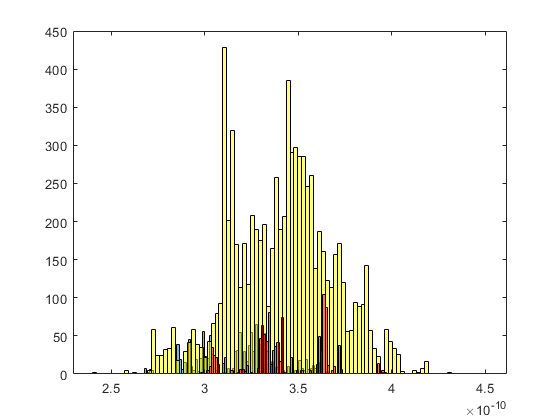

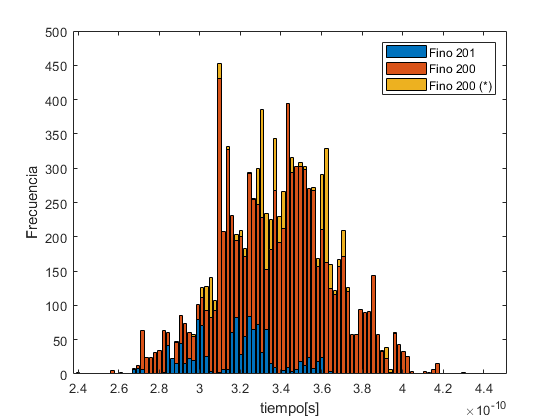

xlabel('tiempo[s]');
ylabel('Frecuencia');
legend({'Fino 201', 'Fino 200', 'Fino 200 (*)'});
% title('Histograma combinado de mediciones finas');
exportgraphics(gcf,'histograma_500k.eps');


Tiempo_final = 200*T + media

Tiempo_final =      1.000338717945312e-06


error = Tiempo_final - T_buscado

error =      3.387179453124527e-10


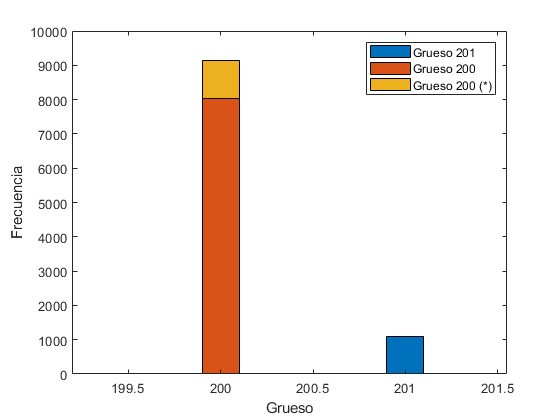

clf;

% Data vectors
data = {coarse_201, coarse_200_buenos, coarse_200_malos};

% Number of bins
N = 8;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = 199.5:0.25:201.5;

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end

bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('Grueso');
ylabel('Frecuencia');
legend({'Grueso 201', 'Grueso 200', 'Grueso 200 (*)'});
exportgraphics(gcf,'histograma_coarse_500k.eps');